# Generate Stepped Cash Flows for Three Different Bonds

This example generates stepped cash flows for three different bonds, all paying interest semiannually. The life span of the bonds is about 18–19 years each: 

- Bond A has two conversions, but the first one occurs on the settlement date and immediately expires.

- Bond B has three conversions, with conversion dates exactly on the coupon dates.

- Bond C has three conversions, with some conversion dates not on the coupon dates. It has the longest maturity. This case illustrates that only cash flows for full periods after conversion dates are affected, as illustrated here:

The following table illustrates the interest-rate characteristics of this bond portfolio.

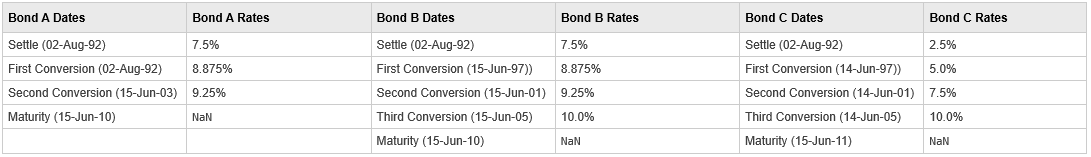

Define the bond specifications.

Settle   = datenum('02-Aug-1992');

ConvDates = [datenum('02-Aug-1992'), datenum('15-Jun-2003'),...
             nan;
            datenum('15-Jun-1997'), datenum('15-Jun-2001'),... 
            datenum('15-Jun-2005');
            datenum('14-Jun-1997'), datenum('14-Jun-2001'),... 
            datenum('14-Jun-2005')];
        
Maturity = [datenum('15-Jun-2010'); 
            datenum('15-Jun-2010'); 
            datenum('15-Jun-2011')];

CouponRates = [0.075 0.08875 0.0925 nan;
               0.075 0.08875 0.0925 0.1;
               0.025 0.05    0.0750 0.1];
Basis = 1;
Period = 2;
EndMonthRule = 1;
Face = 100;

Use [stepcpncfamounts](docid:fininst_ug.btxewww-2302) to compute cash flows and timings.

[CFlows, CDates, CTimes] = stepcpncfamounts(Settle, Maturity, ConvDates, CouponRates)

Visualize the third bond's cash flows (2.5 - 5 - 7.5 - 10) using the [cfplot](docid:finance_ug.btoj6fo-1) function.

cfplot(CDates(3,:),CFlows(3,:));
xlabel('Dates in Serial Number Format')
ylabel('Relative Amounts of Cash Flows')
title('CashFlow of 2.5 - 5 - 7.5 - 10 Stepped Coupon Bond')

*Copyright 2020 The MathWorks, Inc.*